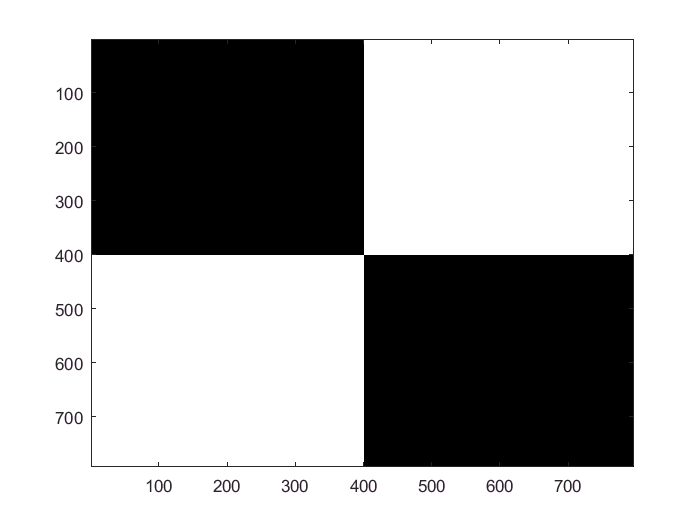

lit = imread('checkers.jpg');
T = double(lit(:,:,1));
clf
imagesc(T); colormap('gray');

T(T == 0) = -1;
T(T == 255) = 1;
T(T >= 128) = 1;
T(abs(T) ~= 1) = -1;
imagesc(T);

arrayT = reshape(T,631228,1);

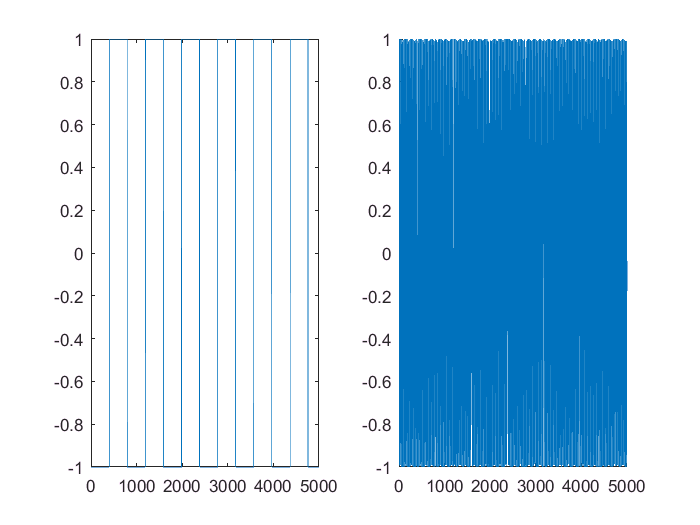

clf
subplot(1,2,1);
plot(arrayT);
xlim([0,5000])
mt = arrayT;                            %array of data
sampleTime = 10;                        %Total length of sample in time
sampleRate = (length(mt))/(sampleTime); %Number of samples per second
t = linspace(0,sampleTime,length(mt));           %array keeping time
w = (sampleRate/3);                     %frequency of cosine wave
c = cos(w*t + .1);                           %array containing carrier wave
xt = mt.*c';                            %assembled signal containing carrier and signal waves
subplot(1,2,2);
hold on
plot(xt)
xlim([0,5000])
hold off

phi = [0];

gain = .6;
alpha = .8;
demodXt = xt'.*cos(w'.*t);

omc = (w*2*pi./sampleRate)*.2;
n = -1000:1000;
h = omc/pi*sinc(omc*n/pi);
filtX = conv(demodXt,h, 'same');
filtY = conv(demodYt,h, 'same');

demodYt = xt'.*-sin(w'.*t);

for k = 2:10000
    newphi(k) = filtX(k)*filtY(k)*1/(gain^2)*4;
    phi(k) = phi(k-1)*alpha+(1-alpha)*filtX(k)*filtY(k)*1/(gain^2)*4;
end
phi(end)

ans = -0.0115

yc = xt*exp(i*phi(end));
demodXt = yc'.*cos(w'.*t + phi);

Matrix dimensions must agree.

omc = (w*2*pi./sampleRate)*.2;
n = -1000:1000;
h = omc/pi*sinc(omc*n/pi);
gain = .6;
filtX = conv(demodXt,h, 'same');

avWind = (100/w)/(1/sampleRate);
for k = 401:length(xt)
    yt1 = cos(w*t + phi).*xt';
    y1 = mean(yt1(k-avWind:k));
    yt2 = -sin(w*t + phi).*xt';
    y2 = mean(yt2(k-avWind:k));
    phi = 4*y1*y2 + phi;
end

Subscript indices must either be real positive integers or logicals.

phi = 4*y1*y2;

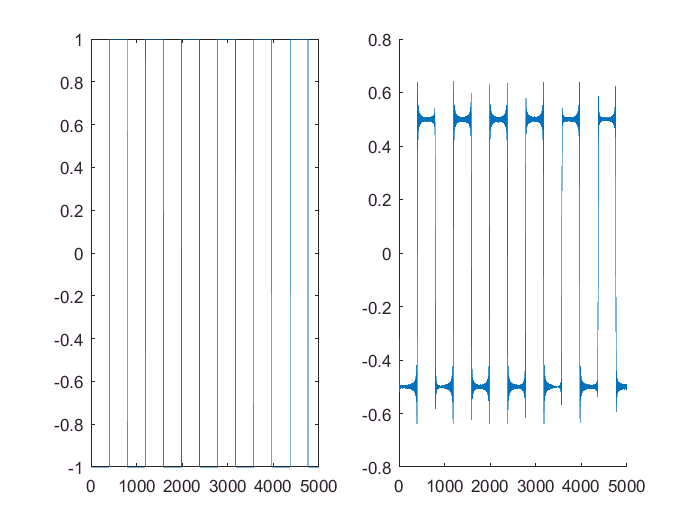

clf
subplot(1,2,1);
plot(arrayT);
xlim([0,5000])
subplot(1,2,2);
hold on
plot(filteredXt)
xlim([0,5000])
hold off

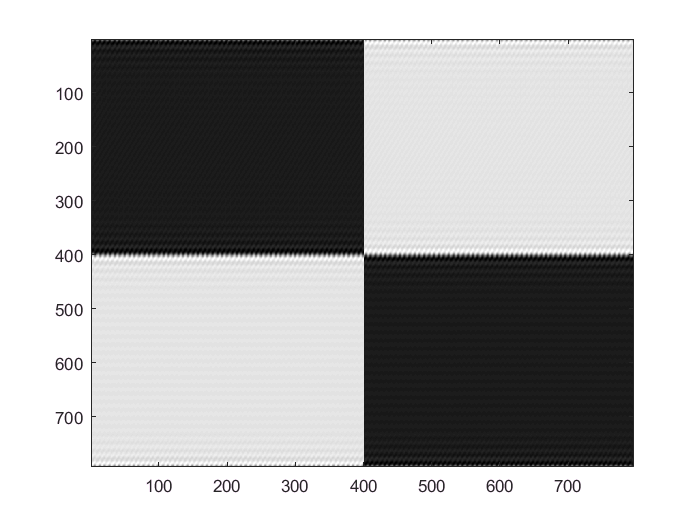

recievedIm = reshape(filteredXt,793,796);
clf
imagesc(recievedIm);

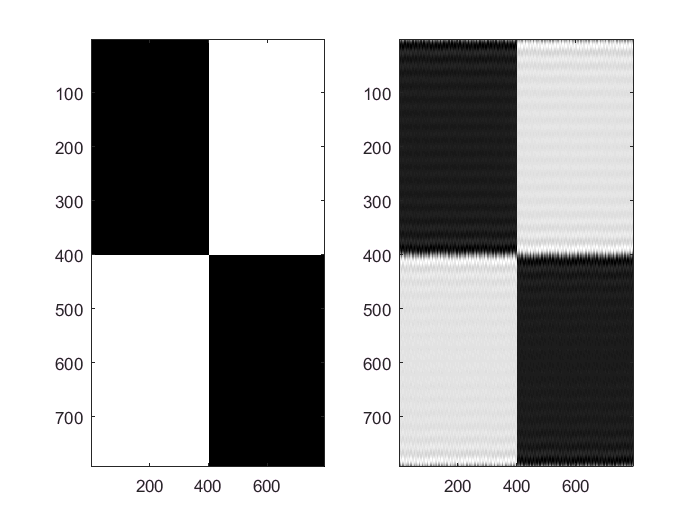

clf
subplot(1,2,1);
imagesc(T);
subplot(1,2,2);
imagesc(recievedIm);